%%summorna av två icke negativa tal ska bli 10 dessa skulle kunna vara x
%%och 10 - x då deras summor är 10 
%% alltså skulle en summa av dessa där en är i kubik och en annan i kvadrat kunna vara
%%  ->> x^3 + (10-x)^2
%%intervallet kommer så vara 0 <= x <= 10
 
x_val = 0:0.1:10;
y_values1 = (func(x_val));
    

plot(x_val,y_values1);
hold on;

y_values1 = (funcprim(x_val));
    

%% jag resonerar att när derivatans värde är 0 så befinner sig den originella funktionen i 
% sitt extrempunkt, denna extrempunkt är även en minimipunkt på intervallet
% synligt i övre graf


%denna newton raphson metod kollar när derivatan blir 0 
tolerance = 0.0001;
x1 = 1.8  ;%%lämpligt startvärde att börja från 
    for i = 2:-0.0001:0.2
        
        a =  funcprim(x1);
        b  = funcprimprim(x1);
        
        x2 = x1  - a/b;
        diff = funcprim(x2) - funcprim(x1);
        if  abs(diff) <= tolerance
            
            break;
        end
        x1=x2;
    
    

    end

adsasndasldn


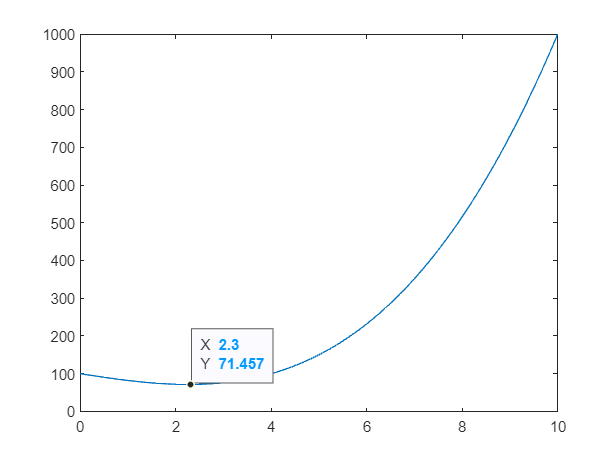


    ax = gca;
chart = ax.Children(1);
datatip(chart,x2,func(x2));


hold off;

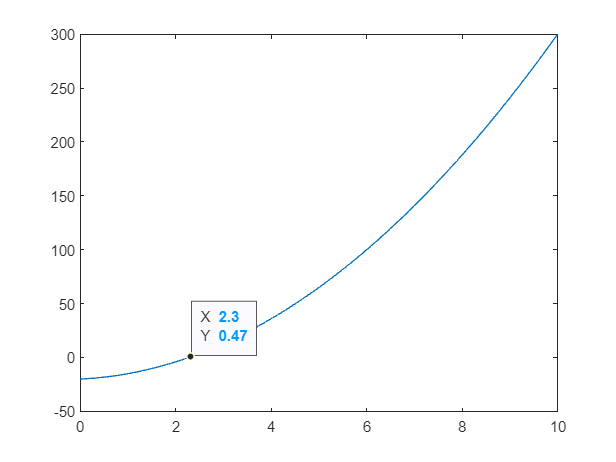



plot(x_val,y_values1);
hold on;

    ax = gca;
chart = ax.Children(1);
datatip(chart,x2,funcprim(x2));


%%alltså uppfylls det minsta värdet vid ungefär x = 2.3






















function y = func(x)
        
     y = x.^3 + (10-x).^2;

end



function y = funcprim(x)
        
     y = 3.*x.^2 + 2.*x - 20;

end


function y = funcprimprim(x)
        
     y = 6.*x + 2;

end
